addpath("Setup\");
addpath('SENSE\');
addpath('shutdown\');
addpath('THINK\');

lidar = setupLidar("COM3")

Lidar Set

   Serial Port Object : Serial-COM3

   Communication Settings 
      Port:               COM3
      BaudRate:           115200
      Terminator:         'LF/CR'

   Communication State 
      Status:             open
      RecordStatus:       off

   Read/Write State  
      TransferStatus:     idle
      BytesAvailable:     0
      ValuesReceived:     2304
      ValuesSent:         31
 



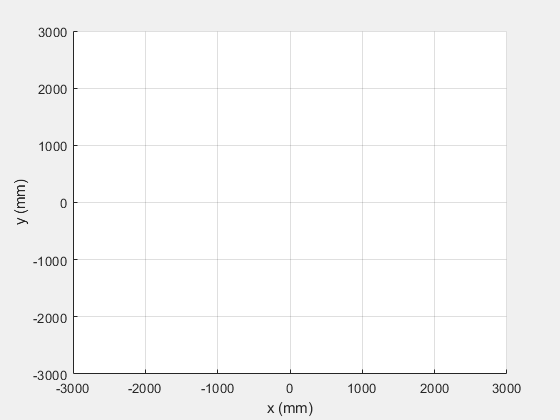

LaserPlot1.figure = figure('Name','LidarTest','NumberTitle','off', ...
    'MenuBar','figure','units','normalized','Visible','on');
LaserPlot1.axis1 = axes('Parent',LaserPlot1.figure,'Units','normalized','NextPlot','replace');
grid(LaserPlot1.axis1, 'on')

LaserRange = line('Parent',LaserPlot1.axis1,'XData',[],'YData',[],'LineStyle','none', ...
        'marker','.','color','b','LineWidth',2);
LaserObj = line('Parent',LaserPlot1.axis1,'XData',[],'YData',[],'LineStyle','none', ...
        'marker','.','color','r','LineWidth',2);

grid on
axis([-3000 3000 -3000 3000])
xlabel('x (mm)')
ylabel('y (mm)')

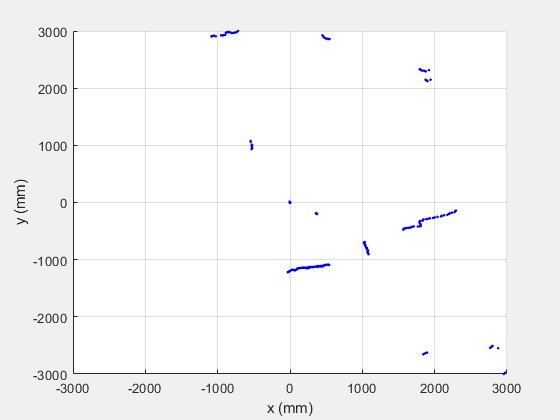

angles = (-120:240/682:120-240/682)*pi/180;
count = 0;

while count < 300
    lidarData = senseLidar(lidar);
    index = lidarOA(lidarData);
    for i=1:length(index)
        
    end
    LaserRange.XData = lidarData.x;   
    LaserRange.YData = lidarData.y;
    drawnow
    count = count +1;
    pause(0.2);
end

shutdownLidar(lidar)

Error using serial/fprintf
Unexpected error: OBJ must be connected to the hardware with FOPEN..

Error in shutdownLidar (line 5)
    fprintf(lidar,'QT');    % write string to quit the lidar

clear